# Randwertprobleme für gewöhnliche Differentialgleichungen

## Einleitung

In der folgenden Arbeit werden skalere Randwertprobleme für gewöhliche Differentialgelichungen zweiter Ordnung numerisch gelöst. Folgendes Problem wird hier verwendet:


$$\frac{d^2}{dt^2}y(t) = a(t) y(t) + b(t)$$


Die Randwerte werden wie folgt angegeben:


$$y(a) = \alpha $$



$$y(b) = \beta
$$


## Vorgegebene Funktion

In der Projektbeschreibung wird eine Funktion angegeben, welche für unterschiedliche $\epsilon$ ausgewertet werden soll.


$$\frac{d^2}{dt^2}y(t) = \frac{-3 \epsilon y(t)}{(\epsilon + t^2)^2}$$


Die foorgegeben Randbedingungen für das Problem sind folgende:

$t \in [-0.1, 0.1]$ und $y(-0.1) = - \frac{0.1}{\sqrt{\epsilon + 0.01}} = \alpha$ und $y(0.1) =  \frac{0.1}{\sqrt{\epsilon + 0.01}} = \beta$

### Berechnung

Hier werdend die Inhomogenitätsfunktionen für das vorgegebene Problem, welche ganz hinten im Skript zu finden sind, verlinkt:

fa = @aInhomogenitaet;
fb = @bInhomogenitaet; % f(t) = a(t)*y(t)+b(t)

Genauso müssen die gegeben Randwerte deffiniert werden.

a = -0.1; 
b = 0.1; % t in [a,b]

Für das Gitter werden hier 1000 Stützstellen verwendet, was sich als guter Kompromiss zwischen Genauigkeit und Laufzeit herausgestellt hat. Im Anschluss wird autmatisch das Gitter generiert.

N = 1000; % Anzahl der Stützstellen (inklusive b)
[h,t] = generateParameters(a,b,N);

Anschließend werden hier die Funktionen für verschiedenes epsilon ausgewertet und darauffolged geplotet.

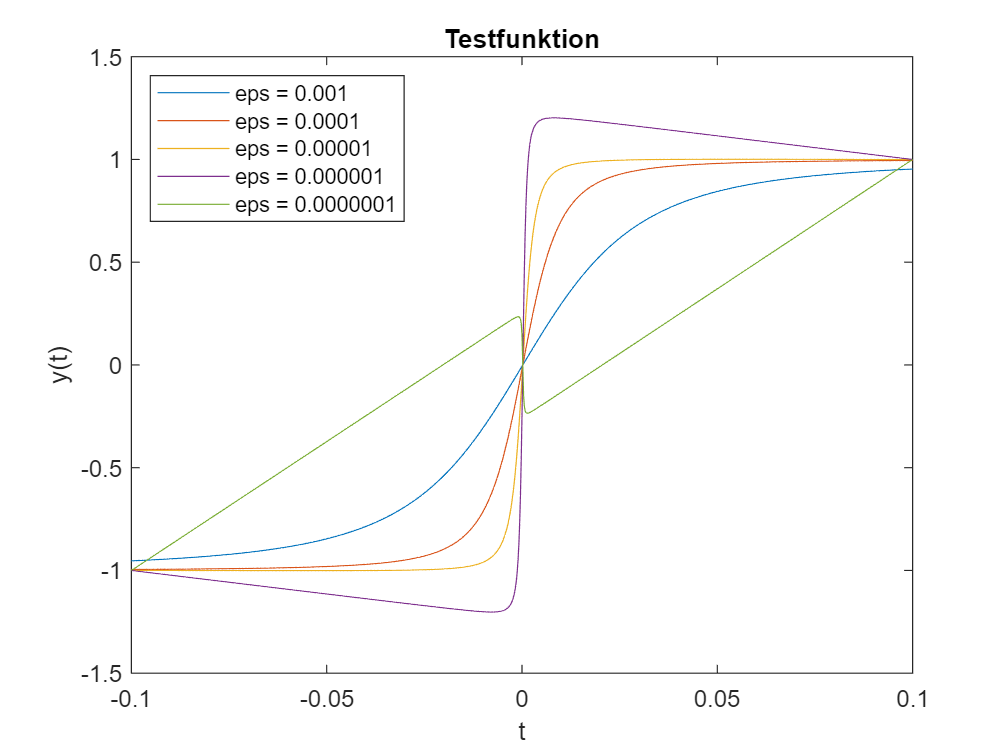

global epsilon;

epsilon = 0.001;
alpha = -0.1/(epsilon+0.01)^(1/2); % y(a) = alpha
beta = 0.1/(epsilon+0.01)^(1/2); % y(b) = beta
y1 = solveEquation(fa,fb,N,h,alpha,beta,t);

epsilon = 0.0001;
alpha = -0.1/(epsilon+0.01)^(1/2); % y(a) = alpha
beta = 0.1/(epsilon+0.01)^(1/2); % y(b) = beta
y2 = solveEquation(fa,fb,N,h,alpha,beta,t);

epsilon = 0.00001;
alpha = -0.1/(epsilon+0.01)^(1/2); % y(a) = alpha
beta = 0.1/(epsilon+0.01)^(1/2); % y(b) = beta
y3 = solveEquation(fa,fb,N,h,alpha,beta,t);

epsilon = 0.000001;
alpha = -0.1/(epsilon+0.01)^(1/2); % y(a) = alpha
beta = 0.1/(epsilon+0.01)^(1/2); % y(b) = beta
y4 = solveEquation(fa,fb,N,h,alpha,beta,t);

epsilon = 0.0000001;
alpha = -0.1/(epsilon+0.01)^(1/2); % y(a) = alpha
beta = 0.1/(epsilon+0.01)^(1/2); % y(b) = beta
y5 = solveEquation(fa,fb,N,h,alpha,beta,t);

plot(t,y1)
hold on 
plot(t,y2)
plot(t,y3)
plot(t,y4)
plot(t,y5)
title('Testfunktion')
legend({'eps = 0.001', 'eps = 0.0001', 'eps = 0.00001', 'eps = 0.000001', 'eps = 0.0000001'},'Location','northwest')
ylabel('y(t)')
xlabel('t')
hold off

### Diskussion

Es ist zu erkennen das die Lösungen mit kleiner werdenen epsilon sich der Heavyside Funktion annäher. Erst bei einem sehr kleinen epsilon wird ein unerwartetes Verhalten festgestellt. Die Lösung weist nämlich  eine stark veränderte Strukur zu den vorherigen Lösungen auf. Diese lässt sich erklären, dadurch das wir hier an die Grenzen unseren hier implementierten Algorithmus befinden. Weiterführend, um eine höhere Genauigkeit zu ereichen, könnte ein variables Gitter implementiert werden, welches sich der Komplexität an der Stelle x=0 anpassen würde und hier eine genauere Berechnung durchführen würde. 

## Vergleich zur analytischen Lösung

Das vorgegeben Problem soll folgende Form haben:


$$\frac{d^2}{dt^2}y(t) = y(t) - 2 t^2 +4$$
 

$t \in [0,1]$  und $y(0) = 3 = \alpha$ und $y(1) = 3e +2 = \beta$

fa = @cInhomogenitaet;
fb = @dInhomogenitaet; 
a = 0; 
b = 1; 
alpha = 3;
beta = 3*exp(1)+2;
N = 500; 

## Berechung

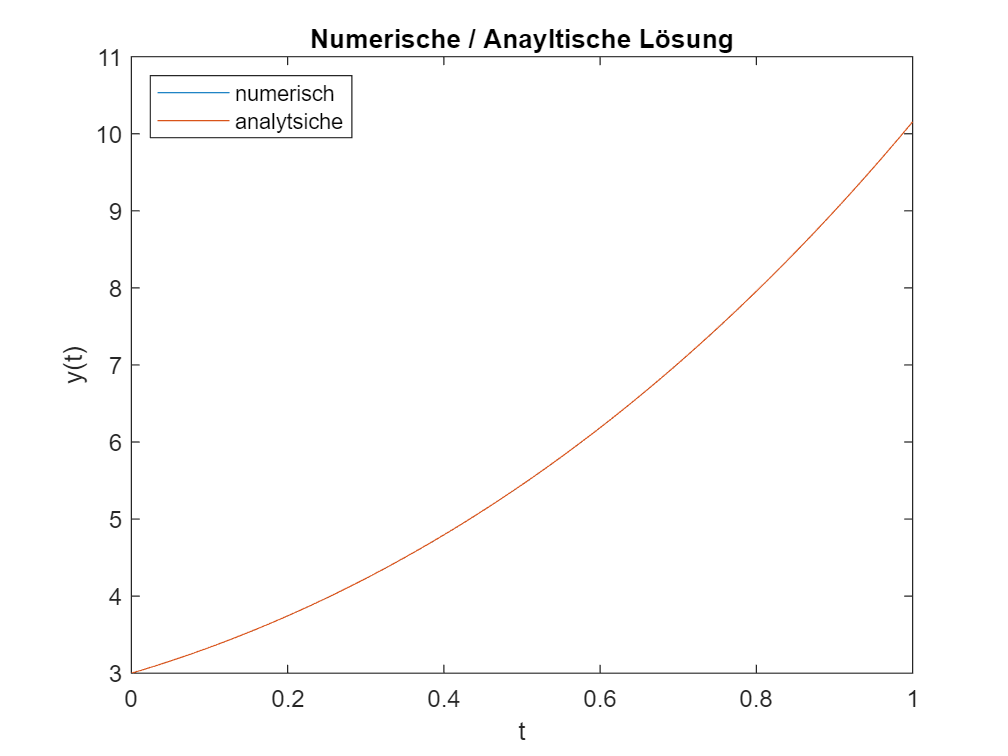

[h,t] = generateParameters(a,b,N);
y1 = solveEquation(fa,fb,N,h,alpha,beta,t);
y2 = 3*exp(t)+2*t.^2;
plot(t,y1)
hold on 
plot(t,y2)
title('Numerische / Anayltische Lösung')
legend({'numerisch', 'analytsiche'},'Location','northwest')
ylabel('y(t)')
xlabel('t')
hold off

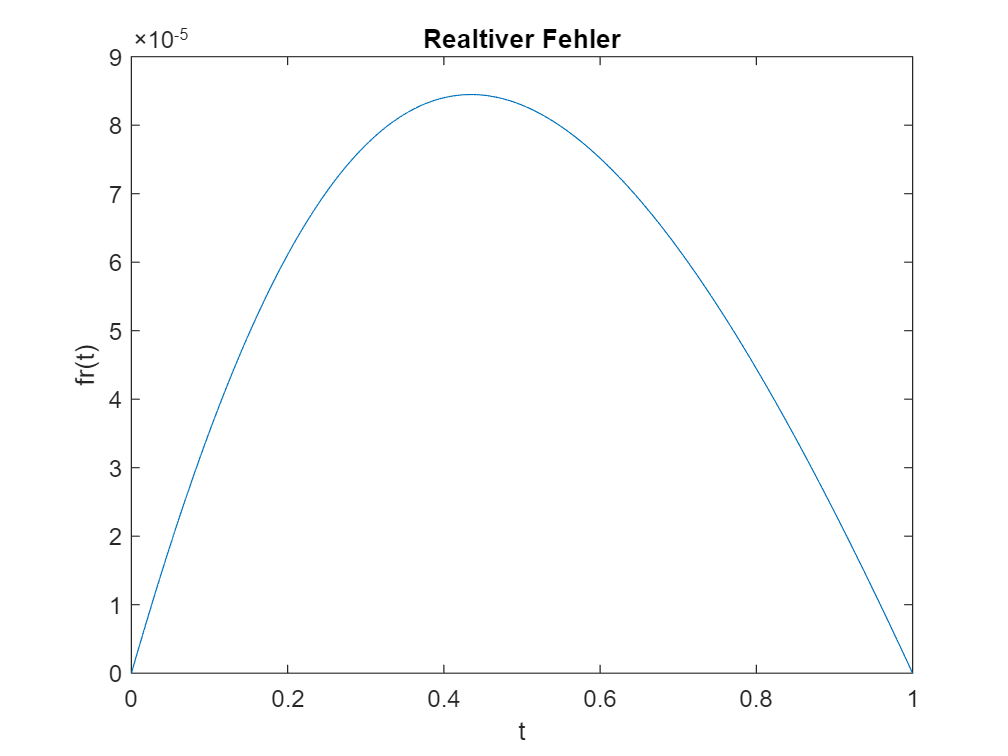

er = abs((y1-transpose(y2)))./y1;
plot(t,er)
hold on 
title('Realtiver Fehler')
ylabel('fr(t)')
xlabel('t')
hold off

## Algortimus

### Gitterimplementierung

Die vorliegende Funktion erstellt ein äquikonstantes Gitter und gibt dieses und dessen Schrittweite zurück.

function [h,t] = generateParameters(a,b,N)
    t = linspace(a,b,N+1);
    h = (b-a)/(N);
end

### Lösungsalgorithmus

Wie in der Theroie diskutiert werden hier die notwendigen Vektoren/Matritzen implentiert. Fh berehnet hier den namensgleichen Vektor in der Theorie. Ebenso berechnet Ah die namensgleiche Matrix in der Theroie.

function output = Fh(fb,N,h,alpha,beta,t) %Erstellen des Vektors für die Inhomogenität
    output = zeros(N-1,1);
    for i  = 1:N-1
        output(i) = h^2*fb(t(i));
    end
    output(1) = output(1) - alpha;
    output(N-1) = output(N-1) - beta;
end

function output = Ah(fa,N,h,t) %Matritze welche die Differentialgleichung abbildet
    output = zeros(N-1,N-1);
    for i=1:N-1
        output(i,i)=-2-h^2*fa(t(i));
    end
    for i=1:N-2
        output(i+1,i)=1;
        output(i,i+1)=1;
    end
end

Die folgende Funktion ist eine Hilfsfunktion damit die Lösung die gleiche Auflösung, wie das Gitter besitzt.

function output = yhTOy(yh,N,alpha,beta) %Hilfsfunktion um das Ergebnis zeichnen zu können
    output = zeros(N+1,1);
    output(1) = alpha;
    output(N+1) = beta;
    for i=2:N
        output(i) = yh(i-1);
    end
end

Die Funktion "solveEquation" gibt die numerisch berechnete Lösung für das Randwertproblem zurück.

function output = solveEquation(fa,fb,N,h,alpha,beta,t) %Lösungsfunktion
    fh = Fh(fb,N,h,alpha,beta,t);
    ah = Ah(fa,N,h,t);
    yh = ah\fh;
    output = yhTOy(yh,N,alpha,beta);
end

## Inhomogenitätsfunktionen

function output = aInhomogenitaet(t) % f(t) = a(t)*y(t)+b(t)
    global epsilon;
    output = -3*epsilon/(epsilon + t.^2)^2;
end

function output = bInhomogenitaet(t) % f(t) = a(t)*y(t)+b(t)
    output = 0;
end

function output = cInhomogenitaet(t) % f(t) = a(t)*y(t)+b(t)
    output = 1;
end

function output = dInhomogenitaet(t) % f(t) = a(t)*y(t)+b(t)
    output = -2*t.^2+4;
end

## Referenzen

Weinmüller E., Auzinger W., (2023). Skriptum: Computernumerik für TPH

[MATLAB Documentation - MathWorks Deutschland](https://de.mathworks.com/help/matlab/) 